data = readtable('C:\Users\SUDARSHAN\Downloads\TCGA_LAML_PCA_READY.csv');


% we are converting the dataset into numeric matrix 
X = table2array(data);

% we are standeredizing here 
X = zscore(X);

%  mean is being centered
X_centered = X - mean(X);

% creating a covariance matrix
C = cov(X_centered);

% doing eigen decamposition 
[V, D] = eig(C);

% sorting eigen values
[eigenvalues, idx] = sort(diag(D), 'descend');
V = V(:, idx);

% choosing number of componentes 
k = 3;
V_k = V(:, 1:k);

% projecting the data
X_manual = X_centered * V_k

X_manual =    -2.8272   -0.9797   -2.3895
    0.0144   -0.9068    1.7186
    0.9308   -1.8838    1.4849
    0.0309    1.1719    0.6106
    0.5730    1.2521    0.7596
    2.8890   -1.3531   -0.5447
   -1.5079    1.8064   -1.4612
   -1.2323   -1.1174   -1.0984
   -2.1448    1.7270    0.5322
   -0.0880   -1.5880    0.7952
   -0.6645   -0.7750   -3.4998
   -3.3580   -1.3174   -0.1564
   -2.4157    1.5480    1.3411
   -1.1685    1.7983   -0.7601
   -0.8182    1.6433   -1.0567


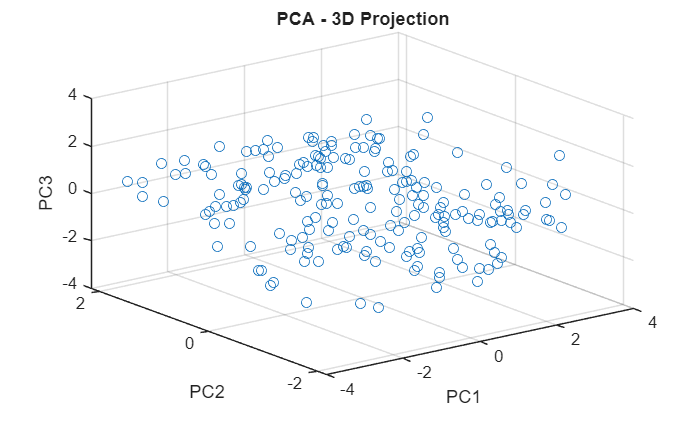


% plotting the graph 
figure;
scatter3(X_manual(:,1), X_manual(:,2), X_manual(:,3));
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');
title('PCA - 3D Projection');
grid on;